clear all; close all;
addpath("Kinematics")
addpath("Trajectory")

pos(1) = ArmPos;
pos(1).phiX = 0.1;
pos(1).phiZ = 0;
pos(1) = pos(1).phiZXtoFullpos(false);

pos =   ArmPos with properties:

         L1: 81
         L2: 165
         L3: 80
         L4: 130
         L5: 130
         L6: 120
         L7: 65
         L8: 50
          X: [0 81]
          Z: [0 246]
    phiXmin: 0.2000
    phiXmax: 1.4708
    phiZmin: -0.4000
    phiZmax: 0.3000
    phi1min: -0.7854
    phi1max: 0.7854
          A: [130 246]
          B: [196.4071 146.0495]
          C: [232.3777 91.9097]
          D: [232.3777 41.9097]
          E: [79.6003 88.9867]
       phiX: 0.1000
       phiZ: 0
       phi1: 0.3544


pos(2) = ArmPos;
pos(2).phiX = 0.15;
pos(2).phiZ = 0.1;
pos(2) = pos(2).phiZXtoFullpos(false);
pos(3) = ArmPos;
pos(3).phiX = 0.12;
pos(3).phiZ = 0.05;
pos(3) = pos(3).phiZXtoFullpos(false);
pos(4) = ArmPos;
pos(4).phiX = 0.08;
pos(4).phiZ = 0;
pos(4) = pos(4).phiZXtoFullpos(false);

n = 2048;
r = linspace(pos(1).D(1), pos(2).D(1), n)

r =   232.3777  232.3748  232.3719  232.3690  232.3661  232.3632  232.3603  232.3574  232.3545  232.3515  232.3486  232.3457  232.3428  232.3399  232.3370  232.3341  232.3312  232.3283  232.3254  232.3225  232.3196  232.3167  232.3138  232.3109  232.3080  232.3051  232.3022  232.2993  232.2964  232.2935  232.2906  232.2877  232.2848  232.2819  232.2790  232.2761  232.2732  232.2703  232.2674  232.2645  232.2616  232.2587  232.2558  232.2529  232.2500  232.2471  232.2442  232.2413  232.2384  232.2355


z = linspace(pos(1).D(2), pos(2).D(2), n)

z =    41.9097   41.9144   41.9191   41.9238   41.9285   41.9331   41.9378   41.9425   41.9472   41.9519   41.9566   41.9613   41.9659   41.9706   41.9753   41.9800   41.9847   41.9894   41.9941   41.9987   42.0034   42.0081   42.0128   42.0175   42.0222   42.0269   42.0316   42.0362   42.0409   42.0456   42.0503   42.0550   42.0597   42.0644   42.0690   42.0737   42.0784   42.0831   42.0878   42.0925   42.0972   42.1018   42.1065   42.1112   42.1159   42.1206   42.1253   42.1300   42.1346   42.1393



tic
posArray = ArmPos.empty([0,n]);
for i=1:n
    posArray(i) = ArmPos;
    posArray(i).D = [r(i),z(i)];
    posArray(i) = posArray(i).DtoC();
    posArray(i) = KineMod.IK_MAU(posArray(i).C);
end
toc

Elapsed time is 0.878839 seconds.


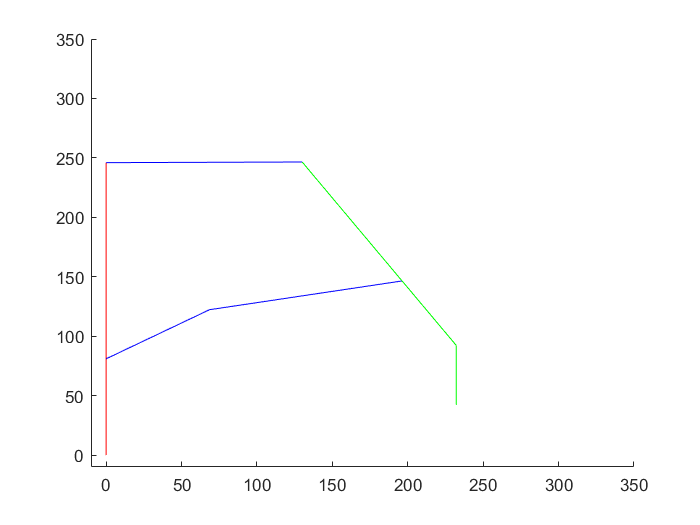


posArray(5).draw();